# Interacting PID Control

Design an interacting PID controllers for the two heaters and sensors on the TCLab. Obtain PID tuning constants $K_c$, $\tau_I$, $\tau_D$, and $K_{ff}$ from the IMC Correlations included below. Use the tuning constants for PID control of temperature for both $T_1$ and $T_2$.

Demonstrate step changes in temperature set point and comment on the performance of the Arduino controller using the calculated constants. Tune the controller by adjusting the constants to improve performance. Comment on the difference between IMC tuning constants and the improved tuning constants in terms of rise time, overshoot, decay ratio, heater fluctuations, or other relevant performance criteria. Report the integral absolute error (IAE) over 10 minutes with setpoint changes given in the test script.


$$IAE_{control} = \sum_{i=0}^n \left| T_{1,SP,i} - T_{1,meas,i} \right| + \left| T_{2,SP,i} - T_{2,meas,i} \right|$$


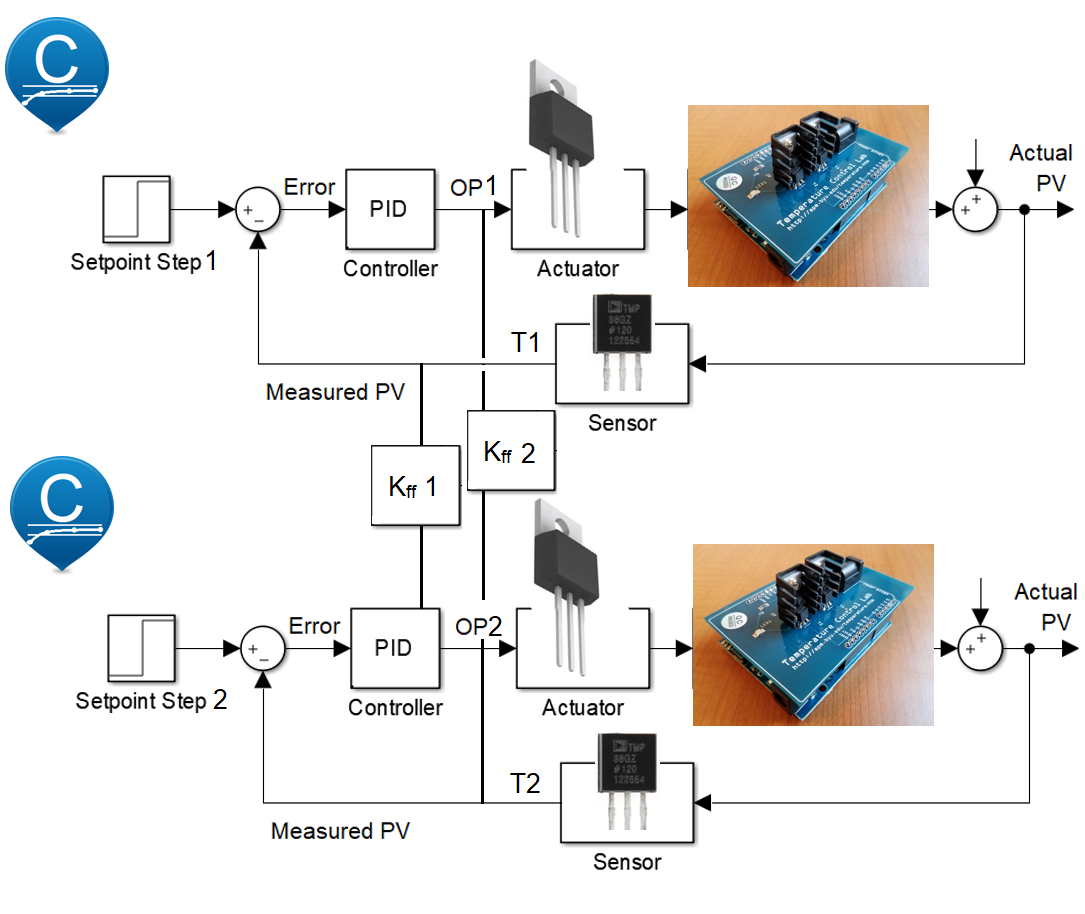

### IMC Correlations

Each process has different characteristics and requirements. The same unit operation at different locations within the same plant can have different control characterstics due to climate, construction, and other variances. In addition, different processes have different objectives: the temperature controller of an oven may seek to achieve the target temperature as fast as possible while the controller for a flowmeter may seek to avoid oscillation and chattering. **Tuning Correlations** provide rough guidance for PID tuning parameters. After using a tuning correlation, the parameters should be further tuned with the specific objective in mind to balance how agressive the response is, and resulting oscillation. This delicate process of adjusting is similar to *tuning* an instrument where fine adjustments are made to achieve the desired pitch.

The most common tuning correlation for PID control is the IMC (Internal Model Control) rules. IMC is an extension of *lambda* tuning by accounting for time delay. The parameters $K_c$, $\tau_p
$, and $\theta_p$ are obtained by fitting dynamic input and output data to a first-order plus dead-time (FOPDT) model (see Lesson 6).


$$\mathrm{Aggressive\,Tuning:} \quad \tau_c = \max \left( 0.1 \tau_p, 0.8 \theta_p \right)$$



$$\mathrm{Moderate\,Tuning:} \quad \tau_c = \max \left( 1.0 \tau_p, 8.0 \theta_p \right)$$



$$\mathrm{Conservative\,Tuning:} \quad \tau_c = \max \left( 10.0 \tau_p, 80.0 \theta_p \right)
$$



$$K_c = \frac{1}{K_p}\frac{\tau_p+0.5\theta_p}{\left( \tau_c + 0.5\theta_p \right)} \quad \quad \tau_I = \tau_p + 0.5 \theta_p \quad \quad \tau_D = \frac{\tau_p\theta_p}{2\tau_p + \theta_p}
$$


## Simulate a PID Controller

Simulate a PID Controller with one of the models determined from parameter estimation exercise.

Kp = 0.6500    
Kd  = 0.1000  
taup = 120.0000   
thetap = 16.0000

tauc = max(0.1 *taup, 0.88 * thetap)

Kc = (taup + 0.5 * thetap) / (Kp * (tauc + 0.5 * thetap))
tauI = taup + 0.5 * thetap
tauD = taup * thetap / (2 * taup + thetap)


Kc = 0;
tauI = 20;
tauD = 0;
Kff = -0.5;
pidPlot(Kc, tauI, tauD, Kff)

## Implement a PID Controller for the TCLab

## View Solution Video

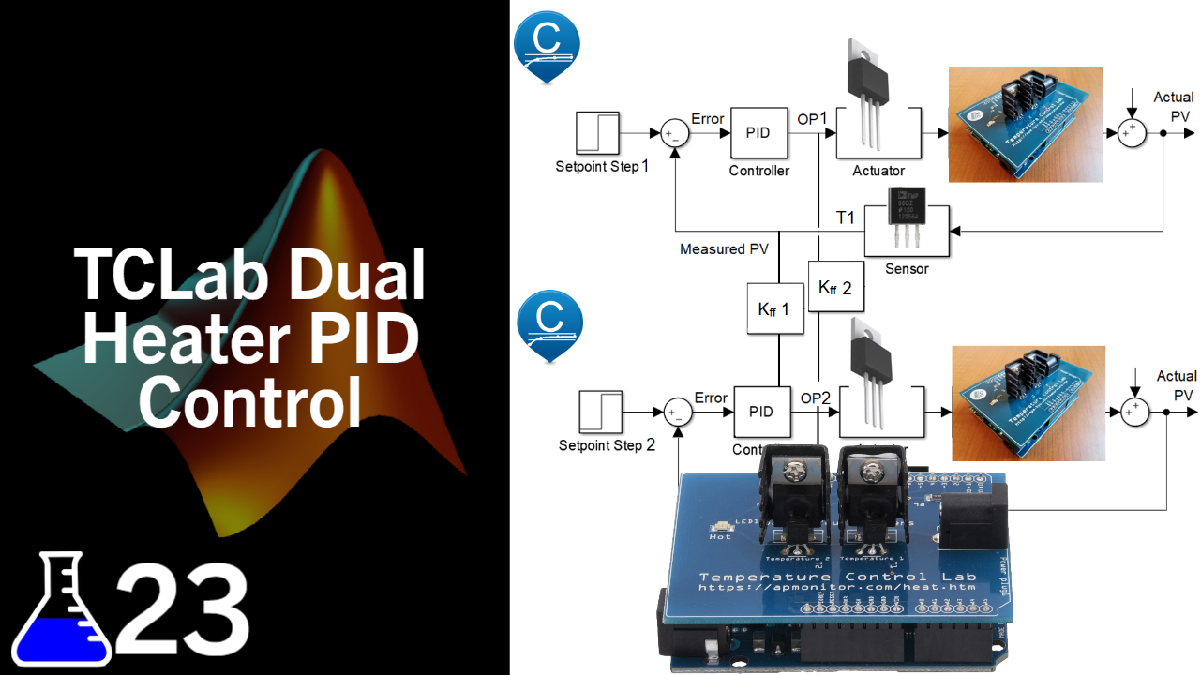

### [Solution Video](https://youtu.be/qXJJz27sRxI)

function dYdt = process(~, Y, u1, u2)
    % Unpack Y
    y1 = Y(1);
    y2 = Y(2);
    % parameters
    Kp = 0.8;
    taup = 165;
    Kd = 0.3;
    % differential equations
    dy1dt = (1.0/taup) * (-(y1-23) + Kp * u1 + Kd * (y2-y1));
    dy2dt = (1.0/taup) * (-(y2-23) + (Kp/2.0) * u2 + Kd * (y1-y2));
    dYdt = [dy1dt; dy2dt];
end

function pidPlot(Kc, tauI, tauD, Kff)
    n = 601;
    tf = 600;

    y0 = [23.0;23.0];
    t = linspace(0,tf,n);  % create time vector
    P1 = zeros(1, n);         % initialize proportional term
    I1 = zeros(1, n);         % initialize integral term
    D1 = zeros(1, n);         % initialize derivative term
    FF1 = zeros(1, n);        % initialize feedforward term
    e1 = zeros(1, n);         % initialize error
    P2 = zeros(1, n);         % initialize proportional term
    I2 = zeros(1, n);         % initialize integral term
    D2 = zeros(1, n);         % initialize derivative term
    FF2 = zeros(1, n);        % initialize feedforward term
    e2 = zeros(1, n);         % initialize error
    OP1 = zeros(1, n);        % initialize controller output
    OP2 = zeros(1, n);        % initialize disturbance
    PV1 = ones(1, n)*23;      % initialize process variable
    PV2 = ones(1, n)*23;      % initialize process variable
    SP1 = ones(1, n)*23;      % initialize setpoint
    SP2 = ones(1, n)*23;      % initialize setpoint
    SP1(10:end) = 60.0;          % step up
    SP1(400:end) = 40.0;         % step up
    SP2(150:end) = 50.0;         % step down
    SP2(350:end) = 35.0;         % step down
    Kc1 = Kc;
    Kc2 = Kc*2.0;
    Kff1 = Kff;
    Kff2 = Kff*2.0;
    iae = 0.0;
    
    % loop through all time steps
    for i =2:n-1
        % simulate process for one time step
        ts = [t(i),t(i+1)];         % time interval
        heaters = [OP1(max(1,i-15)),OP2(max(1,i-15))];
        [~,Y] = ode45(@(t,Y) process(t,Y,heaters(1), heaters(2)), ts, y0);
        y0 = Y(end,:);                  % record new initial condition
        % calculate new OP with PID
        PV1(i+1) = y0(1);              % record T1 PV
        PV2(i+1) = y0(2);              % record T2 PV
        iae = iae + abs(SP1(i)-PV1(i)) + abs(SP2(i)-PV2(i));
        dt = ts(2) - ts(1);            % calculate time step

        % PID for loop 1
        e1(i) = SP1(i) - PV1(i);       % calculate error = SP - PV
        P1(i) = Kc1 * e1(i);           % calculate proportional term
        I1(i) = I1(i-1) + (Kc1/tauI) * e1(i) * dt;  % calculate integral term
        D1(i) = -Kc * tauD * (PV1(i)-PV1(i-1))/dt; % calculate derivative
        FF1(i) = Kff1 * (PV2(i)-PV1(i));
        OP1(i) = P1(i) + I1(i) + D1(i) + FF1(i); % calculate new output
        if OP1(i)>=100
            OP1(i) = 100.0;
            I1(i) = I1(i-1); % reset integral
        elseif OP1(i)<=0
            OP1(i) = 0.0;
            I1(i) = I1(i-1); % reset integral
        end

        % PID for loop 2
        e2(i) = SP2(i) - PV2(i);       % calculate error = SP - PV
        P2(i) = Kc2 * e2(i);           % calculate proportional term
        I2(i) = I2(i-1) + (Kc2/tauI) * e2(i) * dt;  % calculate integral term
        D2(i) = -Kc2 * tauD * (PV2(i)-PV2(i-1))/dt; % calculate derivative
        FF2(i) = Kff2 * (PV1(i)-PV2(i));
        OP2(i) = P2(i) + I2(i) + D2(i) + FF2(i); % calculate new output
        if OP2(i)>=100
            OP2(i) = 100.0;
            I2(i) = I2(i-1); % reset integral
        elseif OP2(i)<=0
            OP2(i) = 0.0;
            I2(i) = I2(i-1); % reset integral
        end
    end

    % plot
    disp('IAE: '+string(round(iae)))
    figure('Renderer', 'painters', 'Position', [10 10 900 600])
    subplot(2,2,1)
    plot(t, SP1, 'k-', 'DisplayName','Setpoint 1 (SP)')
    hold on
    plot(t, PV1, 'r.', 'DisplayName','Temperature 1 (PV)')
    hold off
    ylabel('Temperature ($^\circ$C)', "Interpreter","latex")
    legend('Location',"best")
    subplot(2,2,2)
    plot(t, SP2, 'k-', 'DisplayName','Setpoint 2 (SP)')
    hold on
    plot(t, PV2, 'b.', 'DisplayName','Temperature 2 (PV)')
    hold off
    legend('Location',"best")
    subplot(2,2,3)
    plot(t, OP1, 'b--', 'DisplayName','Heater 1 (OP)')
    ylabel('Heater Setting (%)')
    xlabel('time(sec)')
    legend('Location',"best")
    subplot(2,2,4)
    plot(t, OP2, 'b--', 'DisplayName','Heater 2 (OP)')
    ylabel('Heater Setting (%)')
    xlabel('time(sec)')
    legend('Location',"best")
end